# **PESTools - Example 005 - Showcase of the available ARPES model curves that can be used for fitting**

## Author : PCC

This example shows all of the curve line-shapes that are available to use when fitting to either ARPES or XPS data obtained from the ADRESS beamline. 

- **For ARPES curves:** **2D** **Gaussian**, **2D** **Lorentzian**, **2D** **Voigt** functions are available.

- The **Fermi-Dirac Distribution** **(FDD)** is also used if necessary for fitting states near the Fermi-edge.

- Using the 2D model curves, band dispersions can be plotted and compared to data.

close all; clear all;
pp = plot_props();

# **Symmetric Spot Profiles**

xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e2);

## (1) Gaussian 2D Spot Profile

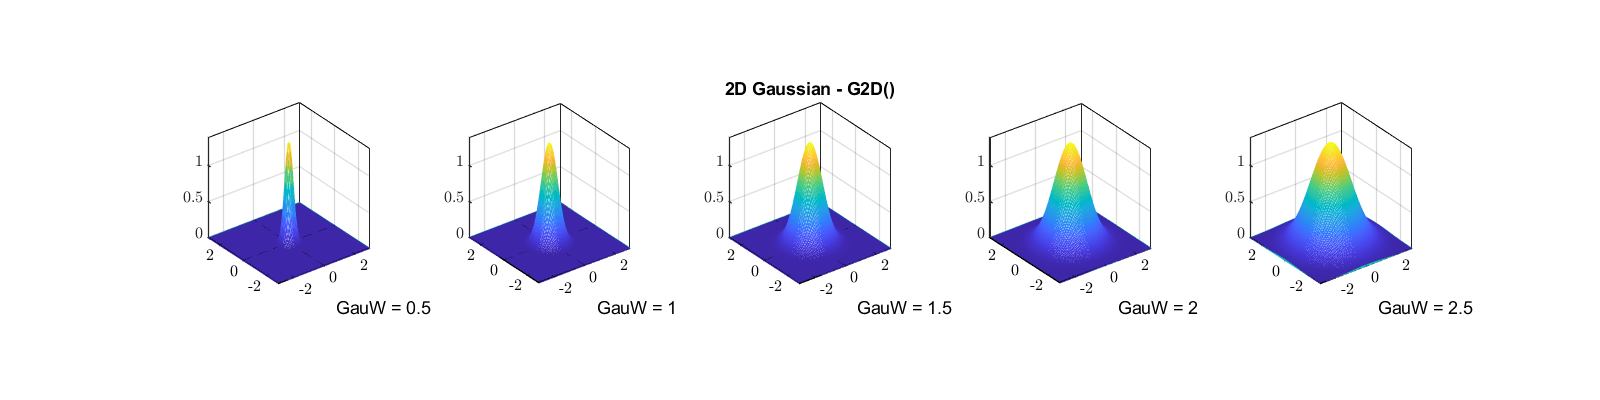

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
fwhm       = 0.5:0.5:2.5;   % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_gauss{i}    = G2D(xdat, ydat, peak, x0, y0, fwhm(i));
    lgnd{i}         = "GauW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(fwhm)
    subplot(1,length(fwhm),i)
    meshz(xdat, ydat, int_gauss{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Gaussian - G2D()'); end
end

## (2) Lorentzian 2D Spot Profile

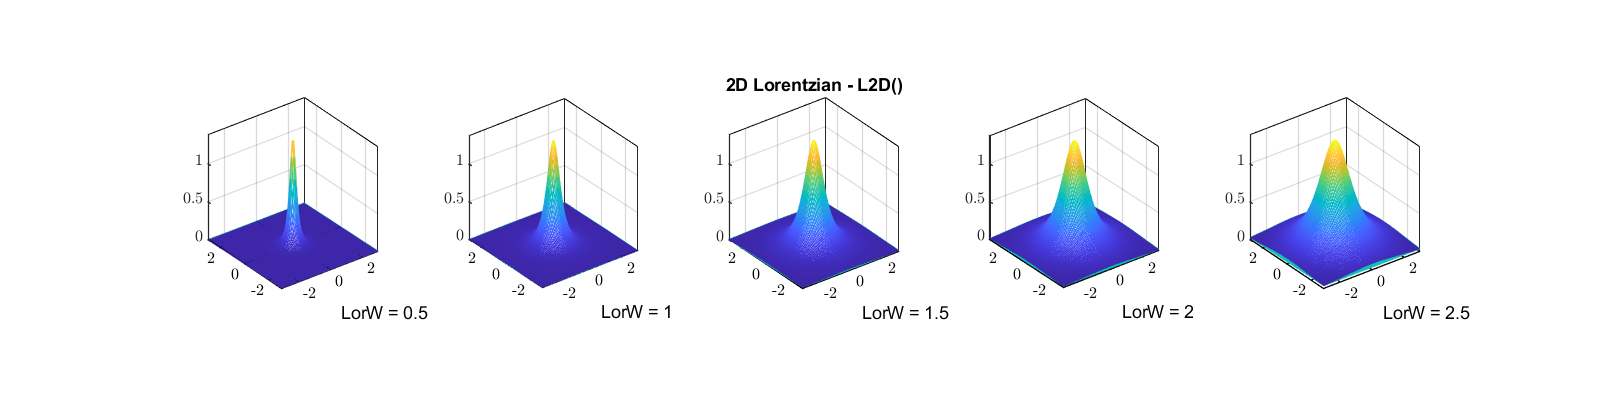

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
fwhm       = 0.5:0.5:2.5;   % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_lorz{i}    = L2D(xdat, ydat, peak, x0, y0, fwhm(i));
    lgnd{i}         = "LorW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(fwhm)
    subplot(1,length(fwhm),i)
    meshz(xdat, ydat, int_lorz{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Lorentzian - L2D()'); end
end

# **Asymmetric Spot Profiles**

xdat = linspace(-3, 3, 1e2);
ydat = linspace(-3, 3, 1e2);

## (1) Asymmetric Gaussian 2D Spot Profile

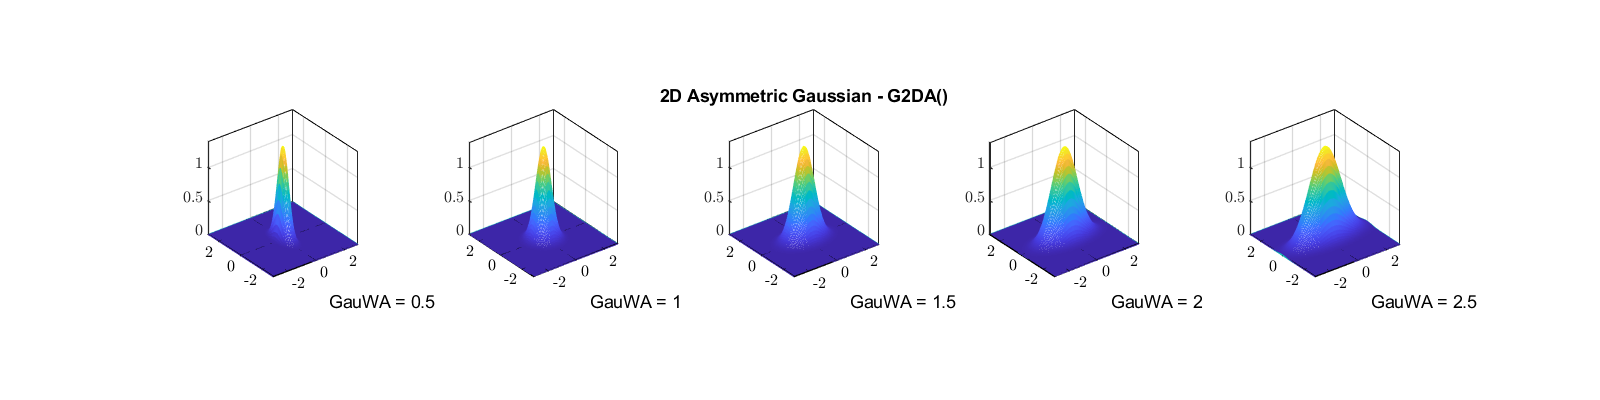

% 1 - Defining the input parameters
peak        = 1.38;         % scalar of the peak beneath the Gaussian.
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
y0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
xfwhm       = 0.5:0.5:2.5;  % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
yfwhm       = 1;            % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the 2D lineshape
lgnd = {};
for i = 1:length(xfwhm)
    int_gauss{i}    = G2DA(xdat, ydat, peak, x0, y0, xfwhm(i), yfwhm);
    lgnd{i}         = "GauWA = " + string(xfwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); 
fig.Position(3) = 4.*pp.fig4x4(1);
fig.Position(4) = 1.*pp.fig4x4(2);
for i = 1:length(xfwhm)
    subplot(1,length(xfwhm),i)
    meshz(xdat, ydat, int_gauss{i});
    gca_props(); axis square;
    xlabel(lgnd{i}); 
    if i == 3; title('2D Asymmetric Gaussian - G2DA()'); end
end

# **Angle-resolved band dispersions plotted using Gaussian spot profiles**

The function 'ARPESCurve()' can be used to call any 2D curve line-shape that is plotted with a particular effective mass and energy.

Using a linear combination of 'ARPESCurve()' outputs, we can then fit to any ARPES band dispersions.

## (1) Generic ARPES Curve

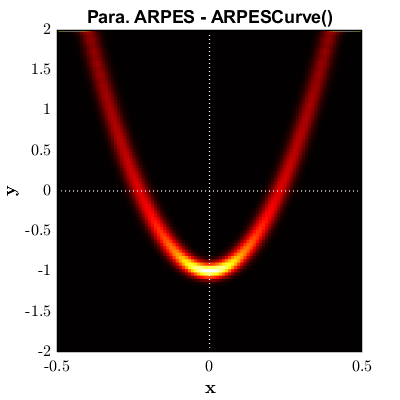

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 2, 1e2)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
% 2 - Calculating the lineshape
zdat    = ARPESCurve(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR);
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); fig.Position(3) = pp.fig4x4(1); fig.Position(4) = pp.fig4x4(2);
hold on;
ImData(xdat, ydat, zdat);
img_props(); 
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('Para. ARPES - ARPESCurve()', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);

## (2) Generic ARPES Curve with FDD Convolution

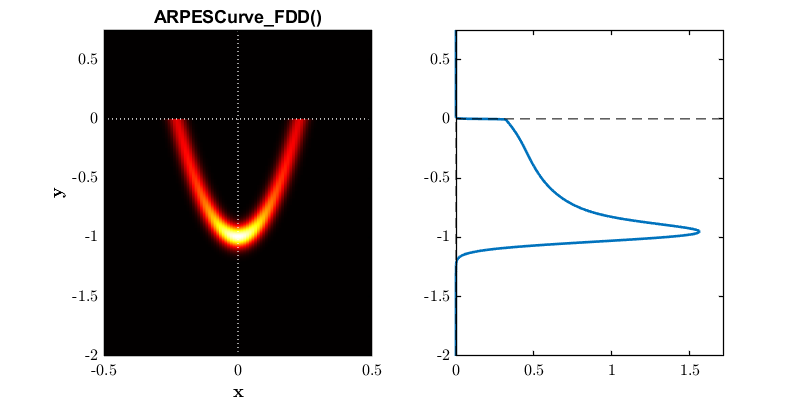

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 0.75, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    = 0.00;         % scalar of the FDD Fermi-Level position.
FDT     = 12.0;        % scalar of the FDD temperature.
% 2 - Calculating the lineshape
zdat    = ARPESCurve_FDD(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT);
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); fig.Position(3) = 2*pp.fig4x4(1); fig.Position(4) = pp.fig4x4(2);
subplot(121); hold on;
ImData(xdat, ydat, zdat); img_props();
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('ARPESCurve_FDD()', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
subplot(122); hold on;
[XCut,DCut] = Cut(xdat, ydat, zdat,'edc',[-0.25,0.25]); plot(DCut, XCut, '-', 'linewidth', 2); gca_props(); axis([0, 1.1*max(DCut(:)), min(ydat(:)), max(ydat(:))]);

## (3) Generic ARPES Curve with FDD Convolution + Gaussian broadening

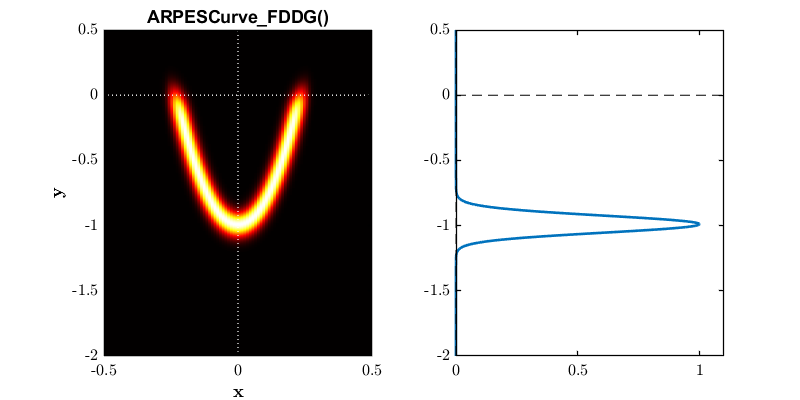

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 0.5, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = -1.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.05;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.15;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.20;         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    = 0.00;         % scalar of the FDD Fermi-Level position.
FDT     = 12.0;        % scalar of the FDD temperature.
FDW     = 0.20;        % scalar of the FDD Gaussian width after convolution.
% 2 - Calculating the lineshape
zdat    = ARPESCurveNorm_FDDG(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW);
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); fig.Position(3) = 2*pp.fig4x4(1); fig.Position(4) = pp.fig4x4(2);
subplot(121); hold on;
ImData(xdat, ydat, zdat); img_props();
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('ARPESCurve_FDDG()', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
subplot(122); hold on;
[XCut,DCut] = Cut(xdat, ydat, zdat,'edc',[-0.02,0.02]); plot(DCut, XCut, '-', 'linewidth', 2); gca_props(); axis([0, 1.1*max(DCut(:)), min(ydat(:)), max(ydat(:))]);

## (4) N Generic ARPES Curves with FDD Convolution + Gaussian broadening + linear background

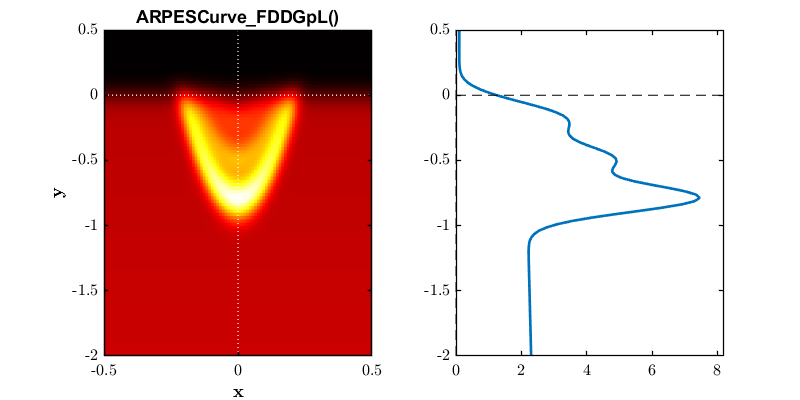

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e2);      % 1xM row vector of the x-axis domain
ydat = linspace(-2, 0.5, 1e2)';       % Nx1 column vector of the y-axis domain
cTYPE   = ["G2DA"; "G2DA"; "G2DA"];   % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = [1.0; 0.5; 0.25];           % scalar of the peak intensity of 2D PE curve.
XLOC    = [0.0; 0.0; 0.0];            % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = [-0.8; -0.5; -0.2];         % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = [0.05; 0.05; 0.05];         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = [0.25; 0.25; 0.25];         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = [0.20; 0.20; 0.20];         % scalar of the effective mass, which governs the curvature of the parabola.
FDEF    =  0.00;        % scalar of the FDD Fermi-Level position.
FDT     =  12.0;        % scalar of the FDD temperature.
FDW     =  0.20;        % scalar of the FDD Gaussian width after convolution.
BGR     =  -0.1;        % scalar of the gradient of the linear background.
BIN     =  2;         % scalar of the y-intercept of the linear background.
BCO     =  0.10;        % scalar of the constant background y-offset value.
% 2 - Calculating the lineshape
zdat    = ARPESCurve_FDDGpL(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR, FDEF, FDT, FDW, BGR, BIN, BCO);
% 3 - Plotting the lineshapes & verifying the FWHM values
fig = figure(); fig.Position(3) = 2*pp.fig4x4(1); fig.Position(4) = pp.fig4x4(2);
subplot(121); hold on;
ImData(xdat, ydat, zdat);
img_props();
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('ARPESCurve_FDDGpL()', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
subplot(122); hold on;
[XCut,DCut] = Cut(xdat, ydat, zdat,'edc',[-0.02,0.02]); plot(DCut, XCut, '-', 'linewidth', 2); gca_props(); axis([0, 1.1*max(DCut(:)), min(ydat(:)), max(ydat(:))]);

# **APPENDIX : A LIST OF USEFUL MISCELLANEOUS ANALYSIS**

## **Appendix I -  Analysing the shift in the VBM / CBM position vs perpendicular angular acceptance window**

## (1) Simulating the InAs valence band

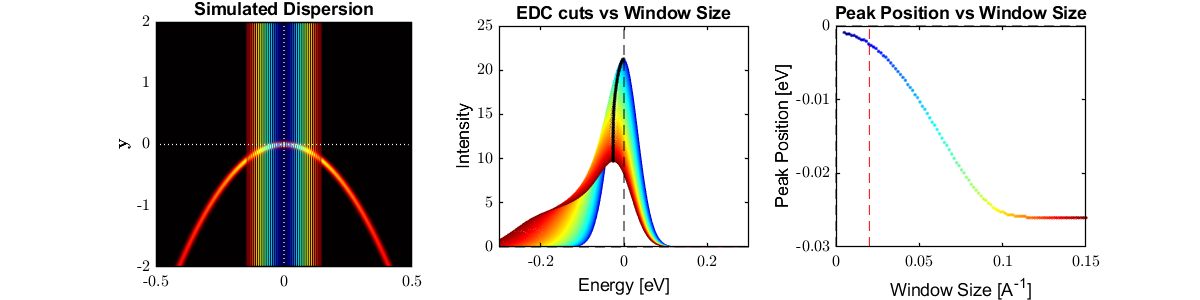

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e3);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 2, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = 0.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.02;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.08;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = -0.32;         % scalar of the effective mass, which governs the curvature of the parabola.
% 2 - Extracting the ARPES dispersion
zdat    = ARPESCurve(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR);
% 3 - Defining the window size
WinVal = linspace(0.005, 0.15, 1e2);
xMode   = 'edc';
for i = 1:length(WinVal)
    Win                         = [-1, 1]*WinVal(i);
    [VB_XCut{i},VB_DCut{i}]     = Cut(xdat,ydat,zdat,xMode,Win);
    [VB_xVal{i}, VB_yVal{i}] = find_peak_loc(VB_XCut{i},VB_DCut{i}, [-0.1, 0.1], "spline", 0);
end
% 4 - Final plot summary
fig = figure(); 
fig.Position(3) = 3.00*pp.fig4x4(1); 
fig.Position(4) = 0.75*pp.fig4x4(2);
col = jet(length(WinVal));
% Plotting the ARPES bands
subplot(131); hold on;
ImData(xdat, ydat, zdat);
% Plotting the window size cuts
for i = 1:5:length(WinVal)
    line([1, 1]*WinVal(i), [-1e5, 1e5], 'Color', col(i,:), 'LineWidth', 0.25, 'Linestyle', '-');
    line([1, 1]*-WinVal(i), [-1e5, 1e5], 'Color', col(i,:), 'LineWidth', 0.25, 'Linestyle', '-');
end
img_props(); 
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('Simulated Dispersion', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
% Plotting the analysis
for i = 1:length(WinVal)
    subplot(132); hold on; plot(VB_XCut{i}, VB_DCut{i}, 'color', col(i,:));
    plot(VB_xVal{i}, VB_yVal{i}, 'k.');
    subplot(133); hold on; plot(WinVal(i), VB_xVal{i}, 'k.', 'color', col(i,:));
end
% Formatting the axes
subplot(132); 
gca_props();
xlim([-0.3, 0.3]);
xlabel('Energy [eV]');
ylabel('Intensity');
title('EDC cuts vs Window Size', 'Interpreter', 'none');
subplot(133); 
gca_props();
ylim([-0.03, 0]);
xlabel('Window Size [A^{-1}]');
ylabel('Peak Position [eV]');
title('Peak Position vs Window Size', 'Interpreter', 'none');
line([0.02 0.02], [-1e5, 1e5], 'Color', [1 0 0], 'LineWidth', 0.75, 'Linestyle', '--');

## (2) Simulating the InAs conduction band

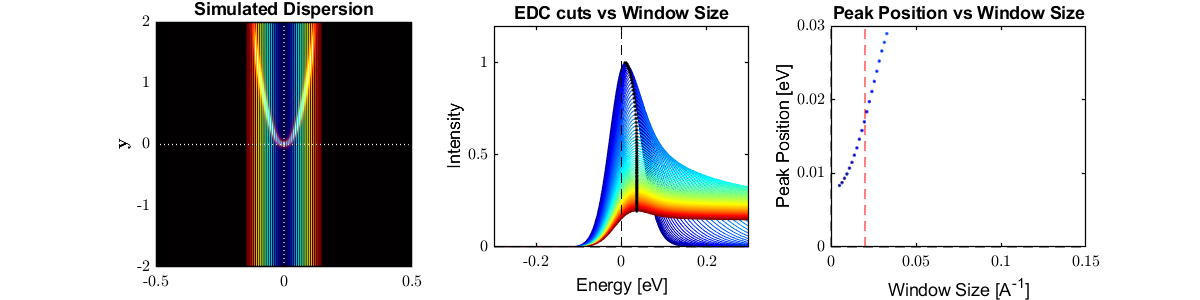

% 1 - Defining the input parameters
xdat = linspace(-0.5, 0.5, 1e3);    % 1xM row vector of the x-axis domain
ydat = linspace(-2, 2, 1e3)';        % Nx1 column vector of the y-axis domain
cTYPE   = "G2DA";       % type of curve to use for fitting. Default: "G2DA" ("G2D", "L2D")
INT     = 1.0;          % scalar of the peak intensity of 2D PE curve.
XLOC    = 0.00;         % scalar of the x-location of the min/max of the 2D parabolic ARPES dispersion.
YLOC    = 0.00;        % scalar of the y-location of the min/max of the 2D parabolic ARPES dispersion.
XFWHM   = 0.02;         % scalar of the x-axis FWHM for each Gaussian (k-resolution)
YFWHM   = 0.08;         % scalar of the y-axis FWHM for each Gaussian (Eb-resolution)
MSTAR   = 0.03;         % scalar of the effective mass, which governs the curvature of the parabola.
% 2 - Extracting the ARPES dispersion
zdat    = ARPESCurveNorm(xdat, ydat, cTYPE, INT, XLOC, YLOC, XFWHM, YFWHM, MSTAR);
% 3 - Defining the window size
WinVal = linspace(0.005, 0.15, 1e2);
xMode   = 'edc';
for i = 1:length(WinVal)
    Win                         = [-1, 1]*WinVal(i);
    [CB_XCut{i},CB_DCut{i}]     = Cut(xdat,ydat,zdat,xMode,Win);
    [CB_xVal{i}, CB_yVal{i}] = find_peak_loc(CB_XCut{i},CB_DCut{i}, [-0.1, 0.1], "spline", 0);
end
% 4 - Final plot summary
fig = figure(); 
fig.Position(3) = 3.00*pp.fig4x4(1); 
fig.Position(4) = 0.75*pp.fig4x4(2);
col = jet(length(WinVal));
% Plotting the ARPES bands
subplot(131); hold on;
ImData(xdat, ydat, zdat);
% Plotting the window size cuts
for i = 1:5:length(WinVal)
    line([1, 1]*WinVal(i), [-1e5, 1e5], 'Color', col(i,:), 'LineWidth', 0.25, 'Linestyle', '-');
    line([1, 1]*-WinVal(i), [-1e5, 1e5], 'Color', col(i,:), 'LineWidth', 0.25, 'Linestyle', '-');
end
img_props(); 
xlabel('$$ \bf  x $$', 'Interpreter', 'latex');
ylabel('$$ \bf  y $$', 'Interpreter', 'latex');
title('Simulated Dispersion', 'Interpreter', 'none');
axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
% Plotting the analysis
for i = 1:length(WinVal)
    subplot(132); hold on; plot(CB_XCut{i}, CB_DCut{i}, 'color', col(i,:));
    plot(CB_xVal{i}, CB_yVal{i}, 'k.');
    subplot(133); hold on; plot(WinVal(i), CB_xVal{i}, 'k.', 'color', col(i,:));
end
% Formatting the axes
subplot(132); 
gca_props();
xlim([-0.3, 0.3]);
xlabel('Energy [eV]');
ylabel('Intensity');
title('EDC cuts vs Window Size', 'Interpreter', 'none');
subplot(133); 
gca_props();
ylim([0, 0.03]);
xlabel('Window Size [A^{-1}]');
ylabel('Peak Position [eV]');
title('Peak Position vs Window Size', 'Interpreter', 'none');
line([0.02 0.02], [-1e5, 1e5], 'Color', [1 0 0], 'LineWidth', 0.75, 'Linestyle', '--');